# Setup

A = zeros(33);
b = zeros(33,1);
[A,b] = discretisation(A,b);

## Full Storage - Oli

trials = 20;
time1 = tic;

for i = 1:trials
    A1 = cholesky_factorisation(A);
    X1 = forward_substitution(A1', b);
    X1 = backward_substitution(A1, X1);
end

avg_time_taken1 = toc(time1)/trials;



% Memory
whos A1

  Name       Size            Bytes  Class     Attributes

  A1        33x33             8712  double              




% Runtime
avg_time_taken1

avg_time_taken1 = 0.0020


% Floating point operations


## Packed Storage - Nik

% needs fixing
trials = 20;
time2 = tic;

A_packed = A(triu(true(size(A))))'; % row packed
A2 = cholesky_factorisation_packed(A_packed);
X2 = forward_substitution_rowpacked(A2, b);

Unrecognized function or variable 'A'.

Error in forward_substitution_rowpacked (line 9)
n = size(A, 2);

X1 = backward_substitution_rowpacked(A2, X2);

avg_time_taken2 = toc(time2)/trials;


% Memory
whos A2

% Runtime
avg_time_taken2

% Floating point operations


## Band Storage - Tyler

%



% Bandwidth

% Fill-in

% Memory

% Runtime

% Floating point operations

## Sparse Storage - Oli

trials = 20;
time4 = tic;

for i = 1:trials
    A_Sparse = sparse(A);
    p = symamd(A_Sparse); % permutation vector for AMD
    S = A_Sparse(p,p); % permute A
    
    A4 = cholesky_factorisation_sparse(S);
    X4 = forward_substitution(A4', b(p));
    X4 = backward_substitution(A4, X4);
    
    p_inv(p) = 1:length(p); % inverse of permatation
    X4 = X4(p_inv);
end

avg_time_taken4 = toc(time4)/trials;



% Bandwidth
Bandwidth_A_Sparse = bandwidth(A_Sparse)

Bandwidth_A_Sparse = 6

Bandwidth_S = bandwidth(S)

Bandwidth_S = 29


% Fill-in


% Memory
whos A_Sparse

  Name           Size            Bytes  Class     Attributes

  A_Sparse      33x33             2528  double    sparse    



whos S

  Name       Size            Bytes  Class     Attributes

  S         33x33             2528  double    sparse    




% Runtime
avg_time_taken4

avg_time_taken4 = 0.0165


% Floating point operations


## CSR Storage - Alex

%



% Memory


% Iterations


% Runtime
time_taken5

% Floating point operations

% Residual norm against iterations plot x4

% Tolerance for visually indistinguishable x4

% Investiate omega for SOR
% Include plot of omega against number of iterations required to converge to tolerance
% Does formula for optimal omega hold

## Visualisation

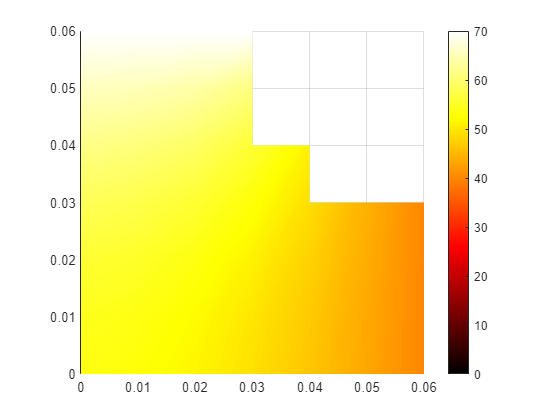

T = zeros(7);
T(7,1:6) = X1(1:6);
T(7,7) = 40;
T(6,1:6) = X1(7:12);
T(6,7) = 40;
T(5,1:6) = X1(13:18);
T(5,7) = 40;
T(4,1:6) = X1(19:24);
T(4,7) = 40;
T(3,1:5) = X1(25:29);
T(3,6) = nan;
T(2,1:4) = X1(30:33);
T(2,5:6) = nan;
T(1,1:4) = 70;

[X,Y] = meshgrid(0:0.01:0.06, 0.06:-0.01:0);

figure
surf(X, Y, T)
view(2) % 2-dimensional (top-down) view
shading interp
colormap hot
colorbar
axis image

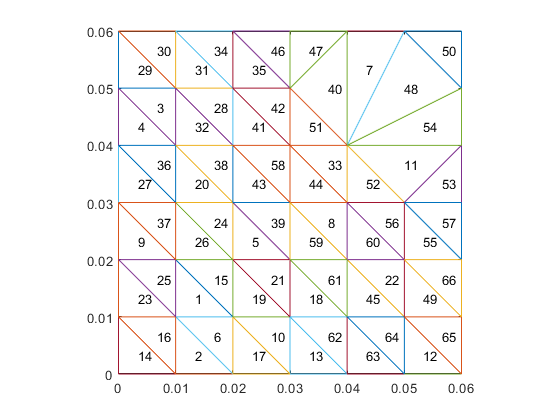


temperatures = T(~isnan(T));
x = X(~isnan(T));
y = Y(~isnan(T));
tri = delaunay(x, y);
figure
trimesh(tri, x, y)
axis image

for i = 1:size(tri,1)
    indices = tri(i,:);
    vertices = [x(indices) y(indices)];
    centroid = mean(vertices);
    text(centroid(1), centroid(2), sprintf('%g',i));
end

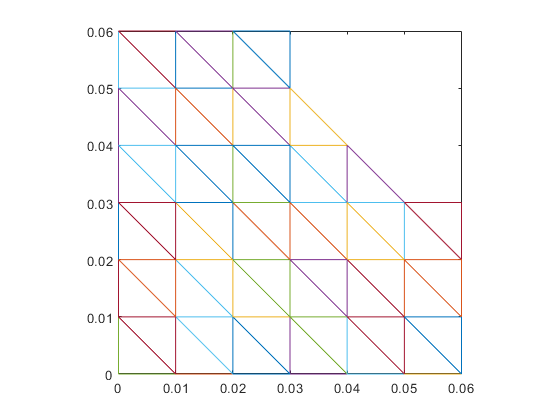

tri([7,11,40,47,48,50,53,54],:) = [];
figure
trimesh(tri, x, y)
axis image

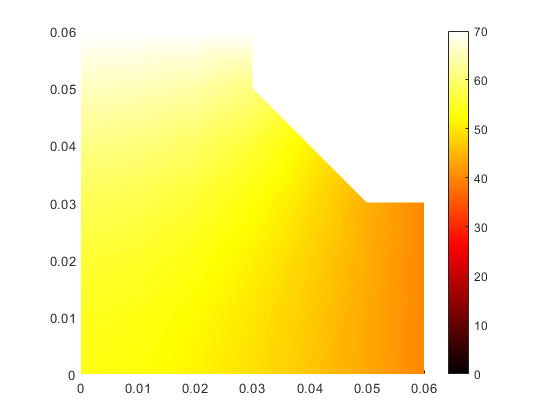


figure
trisurf(tri, x, y, temperatures)
view(2) % 2-dimensional (top-down) view
shading interp
colormap hot
colorbar
axis image
grid off

## Efficiency Comparison - each

%

## Effect Of Ambient Temperature

%